% --- PID Auto-Tune ---
% Make sure sys_speed is in workspace
s = tf('s');
sys_speed = minreal(s * sys_pos);

% --- Auto Tune PID ---
opts = pidtuneOptions('DesignFocus', 'reference-tracking');
[C_pid, info] = pidtune(sys_speed, 'PID', opts);

% Display PID parameters
disp('=== PID Controller Parameters ===');

=== PID Controller Parameters ===


fprintf('Kp (Proportional): %.4f\n', C_pid.Kp);

Kp (Proportional): 90.0095


fprintf('Ki (Integral):     %.4f\n', C_pid.Ki);

Ki (Integral):     62828.8748


fprintf('Kd (Derivative):   %.4f\n', C_pid.Kd);

Kd (Derivative):   0.0000


fprintf('Achieved Phase Margin: %.2f degrees\n', info.PhaseMargin);

Achieved Phase Margin: 78.76 degrees


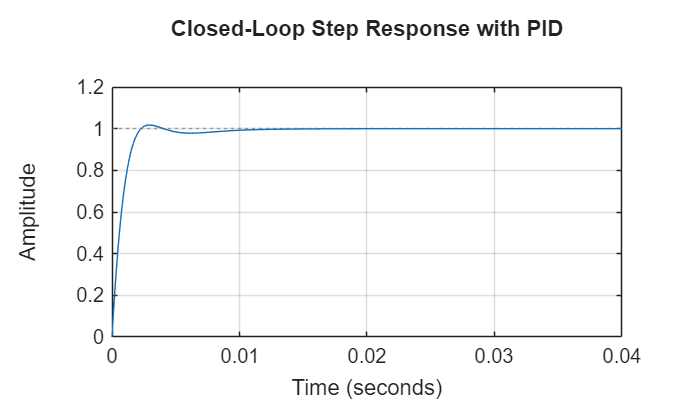


% --- Build Closed Loop System ---
sys_cl = feedback(C_pid * sys_speed, 1);

% --- Step Response ---
figure('Color','w');
step(sys_cl);
title('Closed-Loop Step Response with PID');
grid on;


% Get characteristics
info_step = stepinfo(sys_cl);
K_dc = dcgain(sys_cl);

disp('=== Step Response Characteristics ===');

=== Step Response Characteristics ===


fprintf('DC Gain:        %.4f\n',   K_dc);

DC Gain:        1.0000


fprintf('Rise Time:      %.4f sec\n', info_step.RiseTime);

Rise Time:      0.0014 sec


fprintf('Overshoot:      %.2f %%\n',  info_step.Overshoot);

Overshoot:      1.75 %


fprintf('Settling Time:  %.4f sec\n', info_step.SettlingTime);

Settling Time:  0.0069 sec


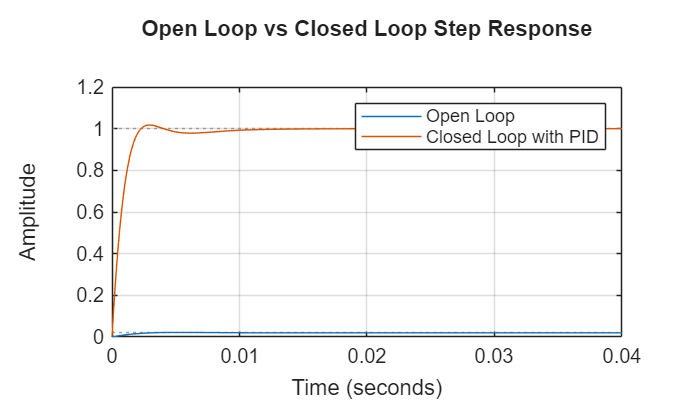


% --- Compare Open vs Closed Loop ---
figure('Color','w');
step(sys_speed, sys_cl);
legend('Open Loop','Closed Loop with PID');
title('Open Loop vs Closed Loop Step Response');
grid on;

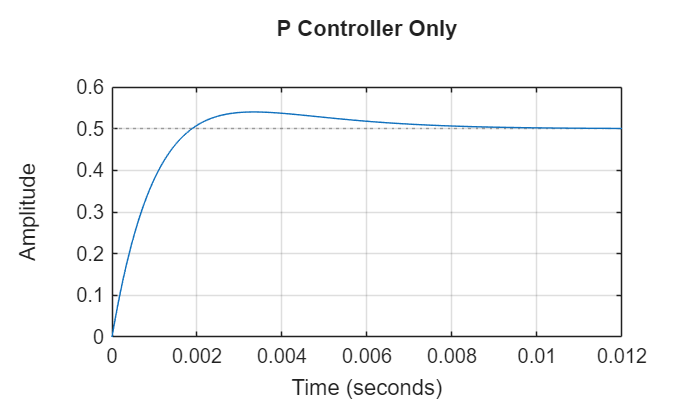

% --- Step 1: P only ---
Kp = 50;
Ki = 0;
Kd = 0;

C_p = pid(Kp, Ki, Kd);
sys_cl_p = feedback(C_p * sys_speed, 1);

figure('Color','w');
step(sys_cl_p);
title('P Controller Only');
grid on;


info_p = stepinfo(sys_cl_p);
fprintf('P Only → Overshoot: %.2f%%  Settling: %.4fs\n',...
    info_p.Overshoot, info_p.SettlingTime);

P Only → Overshoot: 8.02%  Settling: 0.0072s


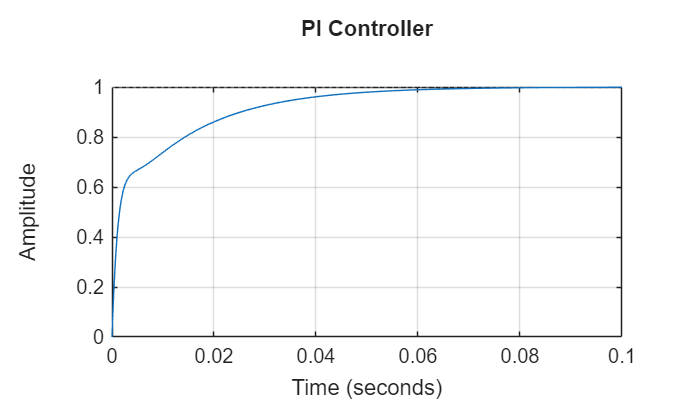

% --- Step 2: PI ---
Kp = 50;
Ki = 6250;
Kd = 0;

C_pi = pid(Kp, Ki, Kd);
sys_cl_pi = feedback(C_pi * sys_speed, 1);

figure('Color','w');
step(sys_cl_pi);
title('PI Controller');
grid on;


info_pi = stepinfo(sys_cl_pi);
fprintf('PI → Overshoot: %.2f%%  Settling: %.4fs\n',...
    info_pi.Overshoot, info_pi.SettlingTime);

PI → Overshoot: 0.00%  Settling: 0.0506s


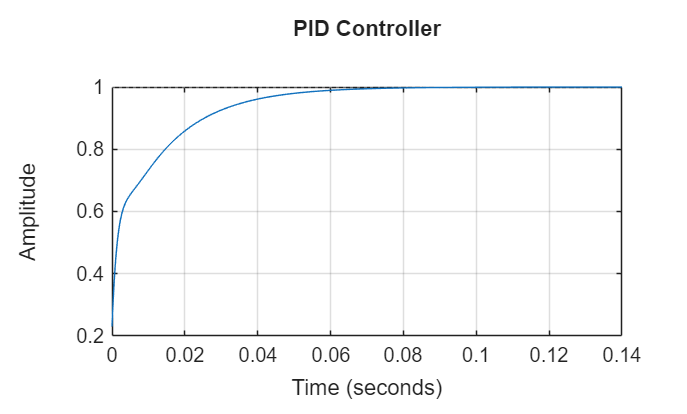

% --- Step 3: PID ---
Kp = 50;
Ki = 6250;
Kd = 0.025;

C_pid = pid(Kp, Ki, Kd);
sys_cl_pid = feedback(C_pid * sys_speed, 1);

figure('Color','w');
step(sys_cl_pid);
title('PID Controller');
grid on;


info_pid = stepinfo(sys_cl_pid);
fprintf('PID → Overshoot: %.2f%%  Settling: %.4fs\n',...
    info_pid.Overshoot, info_pid.SettlingTime);

PID → Overshoot: 0.00%  Settling: 0.0503s


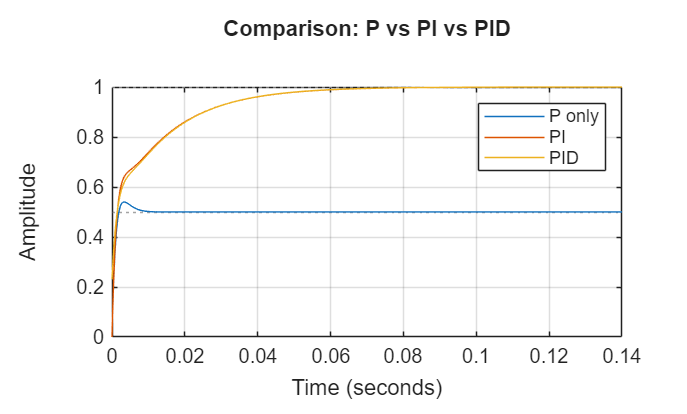


% --- Compare P, PI, PID ---
figure('Color','w');
step(sys_cl_p, sys_cl_pi, sys_cl_pid);
legend('P only', 'PI', 'PID');
title('Comparison: P vs PI vs PID');
grid on;

% Get characteristics
%  PRINT COMPARISON TABLE
%% ============================================
fprintf('=====================================================\n');

fprintf('        STEP RESPONSE CHARACTERISTICS\n');

        STEP RESPONSE CHARACTERISTICS


fprintf('=====================================================\n');

fprintf('%-18s %-12s %-12s %-12s\n', 'Metric', 'P', 'PI', 'PID');

Metric             P            PI           PID         


fprintf('------------------------------------------------\n');

------------------------------------------------


fprintf('%-18s %-12.4f %-12.4f %-12.4f\n', 'DC Gain',       Kp,             Ki,             Kd);

DC Gain            50.0000      6250.0000    0.0250      


fprintf('%-18s %-12.4f %-12.4f %-12.4f\n', 'Rise Time (s)', info_p.RiseTime,   info_pi.RiseTime,   info_pid.RiseTime);

Rise Time (s)      0.0013       0.0251       0.0253      


fprintf('%-18s %-12.2f %-12.2f %-12.2f\n', 'Overshoot (%)', info_p.Overshoot,  info_pi.Overshoot,  info_pid.Overshoot);

Overshoot (%)      8.02         0.00         0.00        


fprintf('%-18s %-12.4f %-12.4f %-12.4f\n', 'Settling (s)',  info_p.SettlingTime, info_pi.SettlingTime, info_pid.SettlingTime);

Settling (s)       0.0072       0.0506       0.0503      


fprintf('%-18s %-12.4f %-12.4f %-12.4f\n', 'Peak',          info_p.Peak,       info_pi.Peak,       info_pid.Peak);

Peak               0.5401       0.9997       1.0000      


fprintf('=====================================================\n');